  clc
clear

dotq=[1;1;1;1;1;1];
ke=100;
kp=10;
%initial value
q=[0;0;0;0;0;0];
qe=[0;0;0;0;0;0];
dqp=[0;0;0;0;0;0];
qp=[0;0;0;0;0;0];
Qa=[0;0;0;0;0;0];
Qb(:,1)=[0;0;0;0;0;0];
dotQ=[0;0;0;0;0;0];
Q=[0;0;0;0;0;0];
Rinf=300;
r=0.;
lambda=0;
%dt
elasticdt=0.005;
plasticdt=0.005/100;
dotlam=0;

Rela=Rinf*sqrt(1-r*exp(-2*lambda*kp/Rinf));
if norm(Q(:,1))-Rela>0
else
    iflag=0;
end

for i=1:40000
    if iflag==0
        Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
        q(:,i+1)=q(:,i)+dotq*elasticdt;
        qe(:,i+1)=q(:,i+1);
        dotQ=(Q(:,i+1)-Q(:,i))/elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        Qb(:,i+1)= Qb(:,i);
        qp(:,i+1)=Qb(:,i+1)/kp;
        lambda(:,i+1)= lambda(:,i);
        dotlam(:,i+1)= dotlam(:,i);
        Rela(:,i+1)= Rela(:,i);
        f(i)=norm(Qa(:,i+1))-Rela(:,i);
        if norm(Q(:,i+1))-Rela(:,i+1)>0
            if Q(:,i+1)'*dotQ<0
                iflag=0;
             Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
        q(:,i+1)=q(:,i)+dotq*elasticdt;
        qe(:,i+1)=q(:,i+1);
        dotQ(:,i+1)=(Q(:,i+1)-Q(:,i))/elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        lambda(:,i+1)= lambda(:,i);
        dotlam(:,i+1)= dotlam(:,i);
       Qb(:,i+1)= Qb(:,i);
       qp(:,i+1)=Qb(:,i+1)/kp;
        Rela(:,i+1)= Rela(:,i);
        f(i)=norm(Qa(:,i+1))-Rela(:,i);
            else
                iflag=1;
                i+1
                syms dt
                Qn=Q(:,i)+dotQ*dt;
                f1=norm(Qn)-Rela(:,i);
                dt1=solve(f1,dt);
                dt=double(dt1);
                 aa=find (dt<0);
                dt(aa)=[];
                Q(:,i+1)=Q(:,i)+dotq*ke*dt;
        q(:,i+1)=q(:,i)+dotq*dt; 
        qe(:,i+1)=q(:,i+1);
        Qa(:,i+1)=Qa(:,i)+dotQ*dt;
        Qb(:,i+1)= Qb(:,i);
        qp(:,i+1)=Qb(:,i+1)/kp;
        lambda(:,i+1)= lambda(:,i);
        dotlam(:,i+1)= dotlam(:,i);
        Rela(:,i+1)= Rela(:,i);
                ik=1;
                f(i)=norm(Qa(:,i+1))-Rela(:,i);
                
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+dotq*plasticdt;
        Qa(:,i+1)=Qa(:,i)+((-(ke)*Qa(:,i)'*dotq*Qa(:,i))/(Qa(:,i)'*Qa(:,i))+ke*dotq)*plasticdt;  
          dotlam(:,i+1)=(Qa(:,i+1)'*dotq*Rinf)/(Qa(:,i+1)'*Qa(:,i+1));
          dqp(:,i+1)=Qa(:,i+1)*dotlam(:,i+1)/Rinf;
          qp(:,i+1)=dqp(:,i+1)*plasticdt+qp(:,i);
%         Q(:,i+1)=Q(:,i)+((-ke*Qa(:,i)'*dotq*Qa(:,i))/(Qa(:,i)'*Qa(:,i))+ke*dotq)*plasticdt;
          Qb(:,i+1)=kp*qp(:,i+1);
          Q(:,i+1)=Qa(:,i+1)+Qb(:,i+1);
        lambda(:,i+1)=lambda(:,i)+(dotlam(:,i+1)*plasticdt);
        Rela(:,i+1)=Rinf*sqrt(1-r*exp(-2*lambda(:,i+1)*kp/Rinf));
        f(i)=norm(Qa(:,i+1))-Rela(:,i);
        if Qa(:,i+1)'*dotQ<0
            iflag=0;
            Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
            q(:,i+1)=q(:,i)+dotq*elasticdt;
            qe(:,i+1)=q(:,i+1);
            dotQ=(Q(:,i+1)-Q(:,i))/elasticdt;
            Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
            lambda(:,i+1)= lambda(:,i);
            dotlam(:,i+1)= dotlam(:,i);
            Rela(:,i+1)= Rela(:,i);
            Qb(:,i+1)= Qb(:,i);
            qp(:,i+1)=Qb(:,i+1)/kp;
            f(i)=norm(Qa(:,i+1))-Rela(:,i);
        end
    end
    ik=0;
end

ans = 246

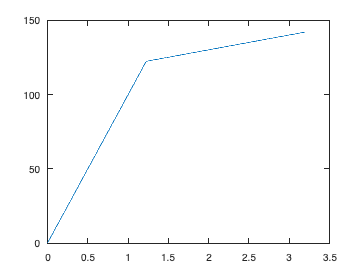


abc=[];
for i=1:size(Rela,2)
    abc(:,i)=norm(Qa(:,i))-Rela(:,i);
end

plot(q(1,:),Q(1,:))